## Espace de solutions qui respecte les butées articulaires et qui évite les singularitées du robot

**Recuperation des solutions calculées dans le fichier ***Config_Robot_Redondant_Point*

On définit tout d'abord les variables du code puis l'espace de solutions sans conditions de filtrage pour atteindre le point cible est recupéré pour ensuite afficher les differentes configuration articulaires possibles en radian

% Charger les solutions depuis le fichier
load('solutions.mat');

% Définir les longueurs des bras
a1 = 2; % Longueur du premier bras
a2 = 3; % Longueur du deuxième bras
a3 = 2; % Longueur du troisième bras
a4 = 2; % Longueur du troisième bras
a5 = 2; % Longueur du troisième bras


% Afficher toutes les configurations trouvées en radian
disp('Configurations possibles du robot en rad pour la position désirée :');

Configurations possibles du robot en rad pour la position désirée :


fprintf('| %-9s | %-9s | %-9s | %-9s | %-9s | %-11s | %-11s | %-9s |\n', 'Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5', 'X_calculé', 'Y_calculé', 'Singularité');

| Theta1    | Theta2    | Theta3    | Theta4    | Theta5    | X_calculé   | Y_calculé   | Singularité |


disp('______________________________________________________________________________________________________________');

______________________________________________________________________________________________________________


for i = 1:size(all_solutions_with_singularities, 1)
    fprintf('| %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-9.4f | %-11.0f | %-11.0f | %-11d |\n', all_solutions_with_singularities(i,:));
end

| 1.0258    | 0.5542    | 5.9352    | 0.4725    | 0.6466    | 0           | 10          | 0           |
| 1.6073    | 5.6913    | 0.3934    | 0.4612    | 0.3711    | 0           | 10          | 0           |
| 1.1404    | 0.2724    | 6.1346    | 0.5320    | 0.5952    | 0           | 10          | 0           |
| 1.5633    | 0.5468    | 5.0782    | 0.3287    | 0.5234    | 0           | 10          | 0           |
| 1.3778    | 0.1581    | 5.8147    | 0.4652    | 0.9089    | 0           | 10          | 0           |
| 1.1748    | 0.2865    | 6.1688    | 0.2040    | 0.9327    | -0          | 10          | 0           |
| 1.0935    | 0.9469    | 5.4680    | 0.0043    | 0.8127    | -0          | 10          | 0           |
| 1.0996    | 0.3498    | 6.1907    | 0.2991    | 0.7827    | -0          | 10          | 0           |
| 1.9071    | 5.4788    | 0.7884    | 0.1836    | 5.3114    | 0           | 10          | 0           |
| 1.2692    | 0.4100    | 5.9028    | 6.1949    | 1.2170    | -0

disp('______________________________________________________________________________________________________________');

______________________________________________________________________________________________________________


## Filtrage des solutions

### Enlever de l'espace les solutions qui ne respectent pas les butées des angles d'articulation et qui sont des positions singulières

Cette partie tri notre espace de solutions, en fonction des butées de chaque articulations et des positions de singularitées. De cette manière, nous pouvons observer dans la table ci-dessous les configurations (en gras), qui respectent bien ces deux conditions.

Ainsi, on a dans la derniere table le resultat final de notre espace de travail qui repond aux differentes conditions de filtrage des solutions 

disp('Butées de chaque theta:')

Butées de chaque theta:


butee = [-90, 90; -90, 90; -90, 90; -90, 90; -90, 90] % Par exemple, [-90, 90] pour tous les angles

butee =    -90    90
   -90    90
   -90    90
   -90    90
   -90    90



% Tri des solutions qui respectant les butees
trisolution = all(all_solutions_deg >= butee(:, 1)' & all_solutions_deg <= butee(:, 2)', 2);

% Vérifier les singularités
singularite = check_singularities(deg2rad(all_solutions(:, 1:5)), a1, a2, a3, a4, a5);

% Ajouter l'information de singularité comme une colonne supplémentaire
all_solutions_with_singularities = [all_solutions, singularite];

% Tableau pour stocker les résultats finaux
resultats_finaux = [];
% Compter le nombre de solutions non prises en charge
nb_solutions_non_prises_en_charge = sum(~solutionok);
disp(['Il y a ', num2str(nb_solutions_non_prises_en_charge), ' solutions qui ne respectent pas les conditions de butées.']);

Il y a 5 solutions qui ne respectent pas les conditions de butées.



% Mise en evidence des configurations qui respectent les butees parmi
% toutes les solutions
disp('Configurations possibles du robot en respectant les butees et sans singularites:');

Configurations possibles du robot en respectant les butees et sans singularites:


fprintf('| %-9s | %-9s | %-9s | %-9s | %-9s | %-11s | %-11s | %-9s |\n', 'Theta1', 'Theta2', 'Theta3', 'Theta4', 'Theta5', 'X_calculé', 'Y_calculé', 'Singularité');

| Theta1    | Theta2    | Theta3    | Theta4    | Theta5    | X_calculé   | Y_calculé   | Singularité |


disp('_____________________________________________________________________________________');

_____________________________________________________________________________________


for i = 1:size(all_solutions_deg, 1)
    if trisolution(i) && ~singularite(i)
        fprintf('| %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.0f | %-9.0f | %-9d |\n', all_solutions_deg(i, :), all_solutions(i, 6), all_solutions(i, 7), singularite(i));
        % Ajouter la solution filtrée au tableau des résultats finaux
        resultats_finaux = [resultats_finaux; all_solutions_deg(i, :), all_solutions(i, 6:7), singularite(i)];
    else
        fprintf('| %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.2f | %-9.0f | %-9.0f | %-9d |\n', all_solutions_deg(i, :), all_solutions(i, 6), all_solutions(i, 7), singularite(i));
    end
end

| 58.78     | 31.75     | -19.94    | 27.07     | 37.05     | 0         | 10        | 0         |


| 92.09     | -33.91    | 22.54     | 26.42     | 21.26     | 0         | 10        | 0         |


| 65.34     | 15.61     | -8.52     | 30.48     | 34.10     | 0         | 10        | 0         |
| 89.57     | 31.33     | -69.04    | 18.83     | 29.99     | 0         | 10        | 0         |
| 78.94     | 9.06      | -26.84    | 26.66     | 52.08     | 0         | 10        | 0         |
| 67.31     | 16.42     | -6.55     | 11.69     | 53.44     | -0        | 10        | 0         |
| 62.65     | 54.25     | 

| 109.27    | -46.09    | 45.17     | 10.52     | -55.68    | 0         | 10        | 0         |


| 72.72     | 23.49     | -21.80    | -5.06     | 69.73     | -0        | 10        | 0         |
| 86.28     | -2.24     | -25.84    | 31.63     | 48.84     | -0        | 10        | 0         |
| 67.31     | 2.08      | 23.58     | 4.58      | 39.33     | 0         | 10        | 0         |
| 65.80     | 19.64     | -5.19     | 4.41      | 57.65     | -0        | 10        | 0         |
| 63.80     | 32.90     | 

| 92.21     | 16.73     | -66.41    | 37.30     | 33.00     | -0        | 10        | 0         |


| 79.71     | 14.15     | -31.41    | 15.17     | 61.37     | 0         | 10        | 0         |
| 78.22     | 43.69     | -58.41    | 0.39      | 43.40     | 0         | 10        | 0         |
| 70.68     | 39.08     | -50.77    | 17.20     | 49.08     | -0        | 10        | 0         |
| 67.55     | 27.05     | -36.27    | 37.92     | 36.40     | -0        | 10        | 0         |
| 63.74     | 32.21     | 

| 90.48     | -13.48    | -22.54    | 50.57     | 25.59     | 0         | 10        | 0         |


| 88.02     | -32.09    | 50.64     | 20.33     | -37.50    | -0        | 10        | 0         |
| 82.43     | 19.34     | -48.49    | 23.91     | 53.03     | -0        | 10        | 0         |
| 75.30     | 12.64     | -25.43    | 27.85     | 49.35     | 0         | 10        | 0         |
| 65.02     | 18.47     | -2.83     | 7.50      | 53.74     | -0        | 10        | 0         |
| 71.81     | 23.19     | 

| 111.47    | -7.58     | -14.35    | 4.48      | -56.01    | -0        | 10        | 0         |


disp('_________________________________________________________________________________________________________');

_________________________________________________________________________________________________________



disp('RESULTATS FINAUX RESPECTANT LES CONDITIONS DE BUTEES ET DE NON SIGULARITE')

RESULTATS FINAUX RESPECTANT LES CONDITIONS DE BUTEES ET DE NON SIGULARITE


fprintf('| %-5s | %-5s | %-5s | %-5s | %-5s | %-5s | %-5s | %-5s |\n', 'Theta1°', 'Theta2°', 'Theta3°', 'Theta4°', 'Theta5°', 'X calculé', 'Y calculé', 'Singularité');

| Theta1° | Theta2° | Theta3° | Theta4° | Theta5° | X calculé | Y calculé | Singularité |


disp(resultats_finaux)

   58.7759   31.7514  -19.9353   27.0712   37.0472    0.0000   10.0000         0
   65.3389   15.6102   -8.5152   30.4808   34.1000    0.0000   10.0000         0
   89.5711   31.3298  -69.0405   18.8329   29.9885    0.0000   10.0000         0
   78.9396    9.0608  -26.8442   26.6553   52.0768    0.0000   10.0000         0
   67.3137   16.4165   -6.5532   11.6875   53.4391   -0.0000   10.0000         0
   62.6505   54.2540  -46.7058    0.2469   46.5629   -0.0000   10.0000         0
   63.0010   20.0415   -5.3010   17.1367   44.8470   -0.0000   10.0000         0
   72.7217   23.4932  -21.7961   -5.0592   69.7298   -0.0000   10.0000         0
   86.2777   -2.2449  -25.8392   31.6350   48.8404   -0.0000   10.0000         0
   67.3143    2.0793   23.5847    4.5820   39.3314    0.0000   10.0000         0
   65.8032   19.6431   -5.1950    4.4090   57.6510   -0.0000   10.0000         0
   63.8017   32.9049  -20.5121    0.0912   61.6170   -0.0000   10.0000         0
   55.5552   31.3645   -8.96

## Visualisation des configurations filtrees du robot non singulières respectant les butees

Nous pouvons observer ici notre robot redondant qui atteint le point cible dans des configuratios qui respectent ces butees articulaires et qui ne sont pas singulières

disp('Visualisation des configurations filtrees du robot respectant les butées')

Visualisation des configurations filtrees du robot respectant les butées


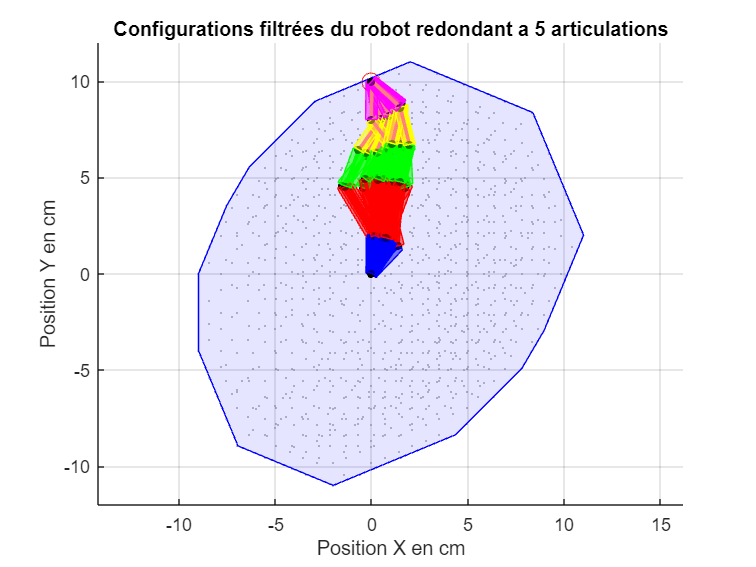

% Initialiser une figure
figure;
hold on;

%Tracer le point désiré en rouge
plot(x_desired, y_desired, 'ro', 'MarkerSize', 10, 'DisplayName', 'Point désiré');

% Initialiser une liste pour stocker les coordonnées atteignables
reachable_points = [];
% Convertir les limites des intervalles de degrés en radians
butee_rad = deg2rad(butee);
% Définir la grille d'angles d'articulation
theta1_range = linspace(butee_rad(1, 1), butee_rad(1, 2), 5);
theta2_range = linspace(butee_rad(2, 1), butee_rad(2, 2), 5);
theta3_range = linspace(butee_rad(3, 1), butee_rad(3, 2), 5);
theta4_range = linspace(butee_rad(4, 1), butee_rad(4, 2), 5);
theta5_range = linspace(butee_rad(5, 1), butee_rad(5, 2), 5);
% Calculer les coordonnées atteignables pour chaque combinaison d'angles
for i = 1:length(theta1_range)
    for j = 1:length(theta2_range)
        for k = 1:length(theta3_range)
            for l = 1:length(theta4_range)
                for m = 1:length(theta5_range)
                    % Calculer les coordonnées de l'effecteur
                    x = a1 * cos(theta1_range(i)) + a2 * cos(theta1_range(i) + theta2_range(j)) + a3 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * cos(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    y = a1 * sin(theta1_range(i)) + a2 * sin(theta1_range(i) + theta2_range(j)) + a3 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k)) + a4 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l)) + a5 * sin(theta1_range(i) + theta2_range(j) + theta3_range(k) + theta4_range(l) + theta5_range(m));
                    % Ajouter les coordonnées à la liste
                    reachable_points = [reachable_points; x, y];
                end
            end
        end
    end
end
%Tracer le nuage de points représentant l'espace de travail atteignable
scatter(reachable_points(:, 1), reachable_points(:, 2), 1, 'filled', 'MarkerFaceColor', [0.5 0.5 0.5]);

% % Convertir les coordonnées en une matrice de points
points_mat = [reachable_points(:, 1), reachable_points(:, 2)];
% % Calculer les contours convexes du nuage de points avec une méthode plus précise
K = convhull(points_mat);
% % Tracer les contours de l'espace de travail
plot(points_mat(K, 1), points_mat(K, 2), 'b', 'LineWidth', .5, 'DisplayName', 'Contours de l''espace de travail');
fill(points_mat(K, 1), points_mat(K, 2), 'b', 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'DisplayName', 'Espace de travail');


% Définir les couleurs pour chaque type de segment
color_segment_OA = 'b'; % Segment OA
color_segment_AB = 'r'; % Segment AB
color_segment_BC = 'g'; % Segment BC
color_segment_CD = 'm'; % Segment CD
color_segment_DE = 'y'; % Segment DE

% Convertir les angles en radians
resultats_finaux_rad = deg2rad(resultats_finaux);

% Visualisation des configurations du robot
for i = 1:size(resultats_finaux_rad, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux_rad(i, 1);
    theta2 = resultats_finaux_rad(i, 2);
    theta3 = resultats_finaux_rad(i, 3);
    theta4 = resultats_finaux_rad(i, 4);
    theta5 = resultats_finaux_rad(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cos(theta1), a1*sin(theta1)]; % Position de l'articulation A
    B = A + [a2*cos(theta1+theta2), a2*sin(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cos(theta1+theta2+theta3), a3*sin(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cos(theta1+theta2+theta3+theta4), a4*sin(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cos(theta1+theta2+theta3+theta4+theta5), a5*sin(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)

    % Tracer le robot pour cette configuration 
    plot([O(1), A(1)], [O(2), A(2)], 'LineWidth', 2, 'Color', color_segment_OA, 'DisplayName', ['Segment OA - Solution ', num2str(i)]); % Segment OA
    plot([A(1), B(1)], [A(2), B(2)], 'LineWidth', 2, 'Color', color_segment_AB, 'DisplayName', ['Segment AB - Solution ', num2str(i)]); % Segment AB
    plot([B(1), C(1)], [B(2), C(2)], 'LineWidth', 2, 'Color', color_segment_BC, 'DisplayName', ['Segment BC - Solution ', num2str(i)]); % Segment BC
    plot([C(1), D(1)], [C(2), D(2)], 'LineWidth', 2, 'Color', color_segment_CD, 'DisplayName', ['Segment CD - Solution ', num2str(i)]); % Segment BC
    plot([D(1), E(1)], [D(2), E(2)], 'LineWidth', 2, 'Color', color_segment_DE, 'DisplayName', ['Segment DE - Solution ', num2str(i)]); % Segment BC
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations

    % Ajouter des rectangles autour des segments
    rectWidth = 0.3; % Ajustez cette valeur selon vos besoins
    drawSegmentRectangle(O, A, rectWidth, 'b');
    drawSegmentRectangle(A, B, rectWidth, 'r');
    drawSegmentRectangle(B, C, rectWidth, 'g');
    drawSegmentRectangle(C, D, rectWidth, 'y');
    drawSegmentRectangle(D, E, rectWidth, 'm');
  
end 


% Calculer les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Configurations filtrées du robot redondant a 5 articulations');
xlabel('Position X en cm');
ylabel('Position Y en cm');


% Affichage de la grille
grid on;

hold off; 

## Affichage des solutions filtrées (butées et singularitées)

Dans cette dernère partie nous pour observer les solutions qui respectent les conditions de butées et de singularitées. 

### 1. Variation de theta pour chaque solution


% Créer une nouvelle figure
figure;

% Boucle sur chaque angle d'articulation
for joint = 1:5
    % Définir la position du subplot dans la grille
    subplot(num_rows, num_cols, joint);
    
    % Titre et étiquettes des axes
    title(['Variation de Theta', num2str(joint), ' pour chaque solution']);
    xlabel('Solution');
    ylabel(['Theta', num2str(joint), '°']); % Modification de l'étiquette en degrés
    grid on;

    hold on; % Garder le graphique actif pour ajouter les données de chaque solution

    % Tracer les valeurs des angles d'articulation pour chaque solution
    for i = 1:size(resultats_finaux, 1)
        % Extraire l'angle d'articulation ajusté pour cette solution
        theta_deg = resultats_finaux(i, joint);

        % Tracer l'angle d'articulation pour cette solution
        plot(i, theta_deg, '+', 'MarkerSize', 5, 'LineWidth', 1, 'Color', 'k','HandleVisibility', 'off');
    end

    % Calculer une interpolation linéaire des données
    x_data = 1:size(resultats_finaux, 1); % Les données x sont simplement les indices des solutions
    y_data = resultats_finaux(:, joint); % Les données y sont les angles d'articulation déjà ajustés

    % Définir un ensemble de points plus fins pour l'interpolation
    finer_x = linspace(1, size(resultats_finaux, 1), 1000); % 1000 points entre le premier et le dernier index

    % Calculer les valeurs interpolées
    interpolated_1 = interp1(x_data, y_data, finer_x, 'spline');
    interpolated_2 = interp1(x_data, y_data, finer_x, 'linear');

    % Tracer la courbe d'interpolation
    plot(finer_x, interpolated_1, 'r-', 'LineWidth', 1, 'DisplayName', 'Interpolation Spline');
    plot(finer_x, interpolated_2, 'k-', 'LineWidth', 1, 'DisplayName', 'Interpolation Lineaire');

    % Trouver la valeur maximale et minimale de theta pour cet angle d'articulation
    max_theta = max(resultats_finaux(:, joint));
    min_theta = min(resultats_finaux(:, joint));
    
    % Ajouter du texte à la position souhaitée
    text(0, max_theta, ['Max: ', num2str(max_theta)], 'Color', 'blue', 'FontSize', 8);
    text(0, min_theta, ['Min: ', num2str(min_theta)], 'Color', 'blue', 'FontSize', 8);
    disp(['Pour theta', num2str(joint), ', Theta max : ', num2str(max_theta), ', Theta min : ', num2str(min_theta)]);

    % Tracer une droite représentant la valeur maximale de theta pour cet angle d'articulation
    plot([1, size(resultats_finaux, 1)], [max_theta, max_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Max Theta', num2str(joint)]);
    
    % Tracer une droite représentant la valeur minimale de theta pour cet angle d'articulation
    plot([1, size(resultats_finaux, 1)], [min_theta, min_theta], '-b', 'LineWidth', 0.6, 'DisplayName', ['Min Theta', num2str(joint)]);

end

Pour theta1, Theta max : 89.5711, Theta min : 46.3251
Pour theta2, Theta max : 57.8489, Theta min : -32.0895
Pour theta3, Theta max : 50.6441, Theta min : -69.0405
Pour theta4, Theta max : 45.4575, Theta min : -15.3847
Pour theta5, Theta max : 69.7298, Theta min : -37.4999


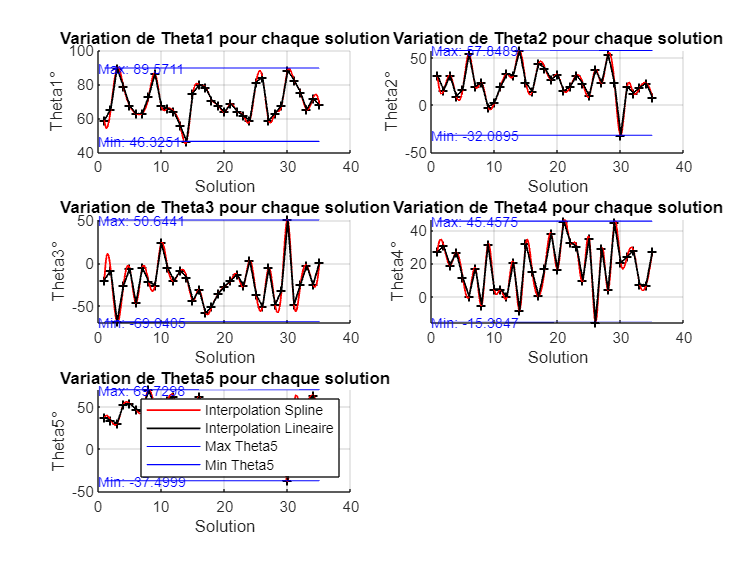


% Légende
legend('show');

### 2.Position des articulations du robot pour les solutions non singulières et qui respectent les butees 

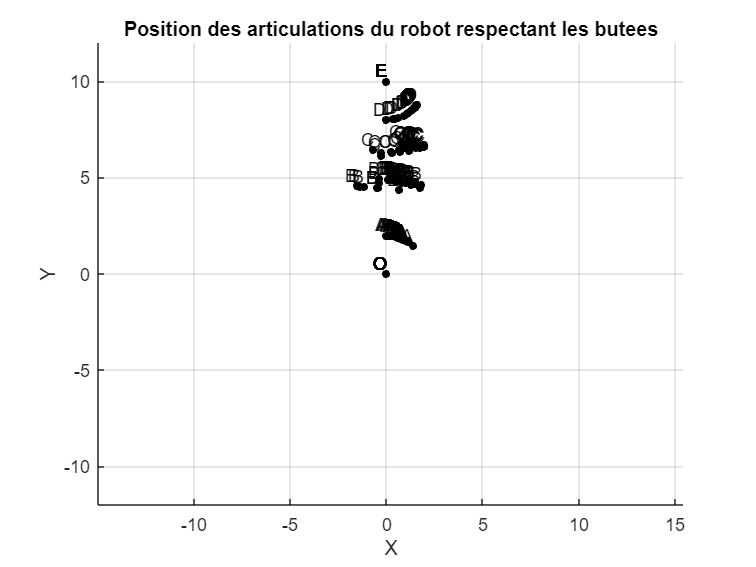

% Position darticulations du robot
figure;
hold on; % Garder le graphique actif pour ajouter les données de chaque solution
% Visualisation des configurations du robot pour les solutions filtrées uniquement
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    theta2 = resultats_finaux(i, 2);
    theta3 = resultats_finaux(i, 3);
    theta4 = resultats_finaux(i, 4);
    theta5 = resultats_finaux(i, 5);

    % Calcul des positions des articulations du robot avec les valeurs des angles d'articulation calculées
    O = [0, 0]; % Position de l'origine
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    B = A + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    C = B + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C (extrémité de l'effecteur)
    D = C + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation C (extrémité de l'effecteur)
    E = D + [a5*cosd(theta1+theta2+theta3+theta4+theta5), a5*sind(theta1+theta2+theta3+theta4+theta5)]; % Position de l'articulation C (extrémité de l'effecteur)
    % Tracer le robot pour cette configuration 
    scatter([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], 20, 'k', 'filled', 'DisplayName', ['Articulations - Solution ', num2str(i)]); % Marques pour les articulations
    % Ajouter les noms des articulations
    text([O(1), A(1), B(1), C(1), D(1), E(1)], [O(2), A(2), B(2), C(2), D(2), E(2)], {'O', 'A', 'B', 'C', 'D', 'E'}, 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
grid on;

% Calc2. uler les limites des axes
xlim([-12, 12]); 
ylim([-12, 12]);
axis equal

% Configurer le titre et les étiquettes des axes
title('Position des articulations du robot respectant les butees');
xlabel('X');
ylabel('Y');

### 3.Position de chaque articulation pour les solutions filtrees

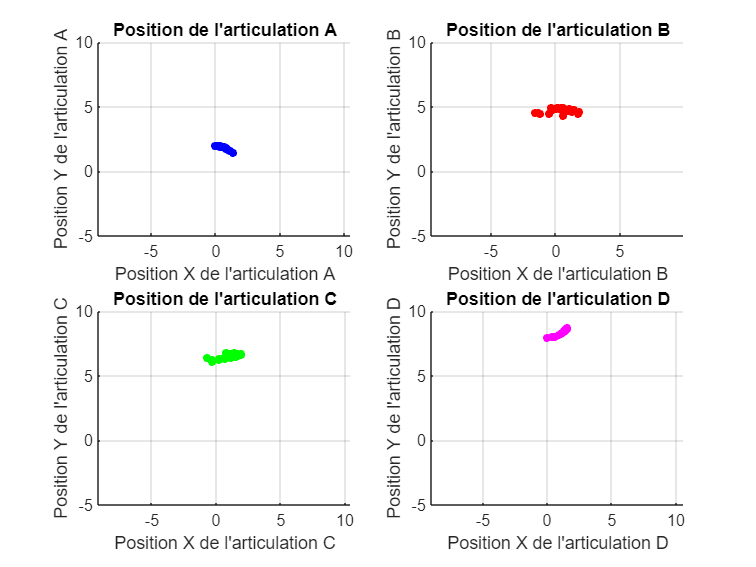

% Créer un graphique distinct pour chaque articulation
figure;

% Articulation A
subplot(2, 2, 1);
title('Position de l''articulation A');
xlabel('Position X de l''articulation A');
ylabel('Position Y de l''articulation A');
hold on;
% Calculer les positions de l'articulation A pour chaque solution finale
A_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    
    % Calculer la position de l'articulation A pour cette solution
    A = [a1*cosd(theta1), a1*sind(theta1)]; % Position de l'articulation A
    A_positions(i, :) = A;
end
scatter(A_positions(:, 1), A_positions(:, 2), 20, 'b', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation B
subplot(2, 2, 2);
title('Position de l''articulation B');
xlabel('Position X de l''articulation B');
ylabel('Position Y de l''articulation B');
hold on;
% Calculer les positions de l'articulation B pour chaque solution finale
B_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    theta2 = resultats_finaux(i, 2);
    
    % Calculer la position de l'articulation B pour cette solution
    B = [a1*cosd(theta1), a1*sind(theta1)] + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)]; % Position de l'articulation B
    B_positions(i, :) = B;
end
scatter(B_positions(:, 1), B_positions(:, 2), 20, 'r', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y


% Articulation C
subplot(2, 2, 3);
title('Position de l''articulation C');
xlabel('Position X de l''articulation C');
ylabel('Position Y de l''articulation C');
hold on;
% Calculer les positions de l'articulation C pour chaque solution finale
C_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    theta2 = resultats_finaux(i, 2);
    theta3 = resultats_finaux(i, 3);
    
    % Calculer la position de l'articulation C pour cette solution
    C = [a1*cosd(theta1), a1*sind(theta1)] + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)] + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)]; % Position de l'articulation C
    C_positions(i, :) = C;
end
scatter(C_positions(:, 1), C_positions(:, 2), 20, 'g', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y

% Articulation D
subplot(2, 2, 4);
title('Position de l''articulation D');
xlabel('Position X de l''articulation D');
ylabel('Position Y de l''articulation D');
hold on;
% Calculer les positions de l'articulation D pour chaque solution finale
D_positions = zeros(size(resultats_finaux, 1), 2);
for i = 1:size(resultats_finaux, 1)
    % Extraire les angles d'articulation pour cette configuration
    theta1 = resultats_finaux(i, 1);
    theta2 = resultats_finaux(i, 2);
    theta3 = resultats_finaux(i, 3);
    theta4 = resultats_finaux(i, 4);
    
    % Calculer la position de l'articulation D pour cette solution
    D = [a1*cosd(theta1), a1*sind(theta1)] + [a2*cosd(theta1+theta2), a2*sind(theta1+theta2)] + [a3*cosd(theta1+theta2+theta3), a3*sind(theta1+theta2+theta3)] + [a4*cosd(theta1+theta2+theta3+theta4), a4*sind(theta1+theta2+theta3+theta4)]; % Position de l'articulation D
    D_positions(i, :) = D;
end
scatter(D_positions(:, 1), D_positions(:, 2), 20, 'm', 'filled');
grid on;
xlim([-5, 5]); % Définir les limites des axes X
ylim([-5, 10]); % Définir les limites des axes Y


% Réglage des espacements entre les sous-graphiques
subplot(2, 2, 1); axis equal; 
subplot(2, 2, 2); axis equal; 
subplot(2, 2, 3); axis equal; 
subplot(2, 2, 4); axis equal;

## Fonctions de génération de rectangles et de prise en charge des singularites

function drawSegmentRectangle(startPoint, endPoint, rectWidth, color)
    % Calcule la longueur et l'angle du segment
    segmentLength = norm(endPoint - startPoint);
    segmentAngle = atan2(endPoint(2) - startPoint(2), endPoint(1) - startPoint(1));
    
    % Calcule les coordonnées des coins du rectangle
    dx = rectWidth * cos(segmentAngle + pi/2);
    dy = rectWidth * sin(segmentAngle + pi/2);
    rectPoints = [startPoint(1) - dx, startPoint(2) - dy;
                  startPoint(1) + dx, startPoint(2) + dy;
                  endPoint(1) + dx, endPoint(2) + dy;
                  endPoint(1) - dx, endPoint(2) - dy;
                  startPoint(1) - dx, startPoint(2) - dy];
    
    % Trace le rectangle
    fill(rectPoints(:, 1), rectPoints(:, 2), color, 'EdgeColor', color, 'FaceAlpha', 0.5);
end

function singularite = check_singularities(theta_solutions, a1, a2, a3, a4, a5)
    % Initialisation du vecteur indiquant la singularité pour chaque configuration
    singularite = false(size(theta_solutions, 1), 1);
  
    % Boucle sur toutes les solutions de theta
    for i = 1:size(theta_solutions, 1)
        % Extraire les valeurs de theta
        theta = theta_solutions(i, :);
        % Extraire les valeurs de theta individuellement
        theta1 = theta(1);
        theta2 = theta(2);
        theta3 = theta(3);
        theta4 = theta(4);
        theta5 = theta(5);
        % Calculer les dérivées partielles
        dx_dtheta1 = -a1*sin(theta1) - a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dx_dtheta2 = -a3*cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a2*cos(theta1)*cos(theta2) - a2*sin(theta1)*sin(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dx_dtheta3 = a3*sin(theta3)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a4*sin(theta4)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2)) + a5*sin(theta5)*(sin(theta1)*sin(theta2) - cos(theta1)*cos(theta2));
        dx_dtheta4 = -a4*sin(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a5*sin(theta5)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2));
        dx_dtheta5 = -a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

        dy_dtheta1 = a1*cos(theta1) + a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a2*cos(theta2)*sin(theta1) + a2*cos(theta1)*sin(theta2) + a4*cos(theta4)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) + a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) + sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))) + a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dy_dtheta2 = a3*cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a3*sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - a2*sin(theta1)*sin(theta2) - a2*cos(theta1)*cos(theta2) - a4*sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))));
        dy_dtheta3 = - a3*sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
        dy_dtheta4 = - a4*sin(theta4)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) - a5*sin(theta5)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1));
        dy_dtheta5 = a5*cos(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)) + sin(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2))) - sin(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) - a5*sin(theta5)*(cos(theta4)*(cos(theta3)*(cos(theta1)*cos(theta2) - sin(theta1)*sin(theta2)) - sin(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1))) + sin(theta4)*(cos(theta3)*(cos(theta1)*sin(theta2) + cos(theta2)*sin(theta1)))));

        % Construire la Jacobienne
        J = [dx_dtheta1, dx_dtheta2, dx_dtheta3, dx_dtheta4, dx_dtheta5; 
         dy_dtheta1, dy_dtheta2, dy_dtheta3, dy_dtheta4, dy_dtheta5];
        rank(J);    
       % Vérifier le rang de la matrice jacobienne
        if rank(J) < min(size(J))
            % Indiquer que cette configuration est singulière
            singularite(i) = true;
        end
       
    end
end
